# How photons become electrons and preserve the Poisson distribution

I have been asked from time-to-time why the distribution of electrons in a pixel is Poisson, given that the distribution of photons in the sensor irradiance is Poisson.  What is it that allows the Poisson distribution to be preserved, although there is a transformation from light to electrons?

Here is the idea.

## A Poisson distribution

The key property of a Poisson distribution is that the likelihood of an 'event' is the same over each small interval of time.  Thus, if we have a small interval of time, $\delta T$ the probability that a photon will arrive is constant, $\rho$. We can simulate the set of photon arrivals this way, using the binomial distribution for each moment in time.

deltaT    = 1e-6;     % A microsecond
rho       = 1e-4;     % Chance of a photon in deltaT
T = deltaT:deltaT:1;  % Time samples
photons = binornd(1,rho,length(T),1);  % The binomial random distribution

At each moment in time there is one event that either happens or not with probability $\rho$.

Here is a plot of the moments when there is (1) or is not (0) a photon.

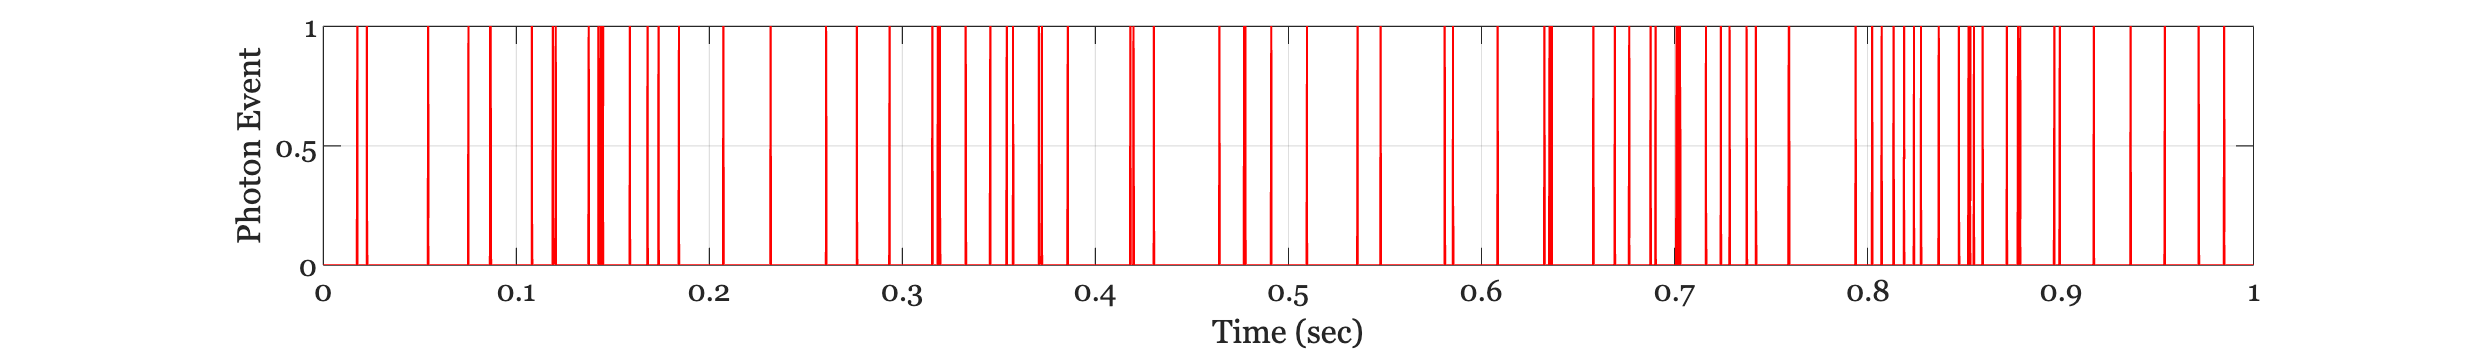

f = ieNewGraphWin; plot(T,photons);
set(f,'Position',[100 100 256 64]);

xlabel('Time (sec)');
ylabel('Photon Event'); grid on


fprintf('In a second, there were %d photons\n',sum(photons));

In a second, there were 88 photons


## Photon to electron conversion

Not every photon turns into an electron.  Suppose the probability of conversion is 0.5.  Then, whenever we have a photon, it has a chance $\epsilon$ of creating an electron in the pixel.

epsilon = 0.5;

So the chance that we have a photon converts into an electron at each moment in time is quite high.  We put a 1 in each interval of time when the photon would in fact convert to an electron.  Notice that this is also a Poisson random variable.  So we can represent it as a series of 0s and 1s.

eConversion = binornd(1,epsilon,length(T),1);

This is not worth plotting because with $\epsilon$ so large and a million sample points, the graph will just look like a solid red square.

## The conversion

We will create an electron in the interval $\delta T$ if 

- There was a photon in that interval, and 

- The electron conversion value is also 1.

electrons = photons .* eConversion;

The electrons are a subset of the times when there is a photon

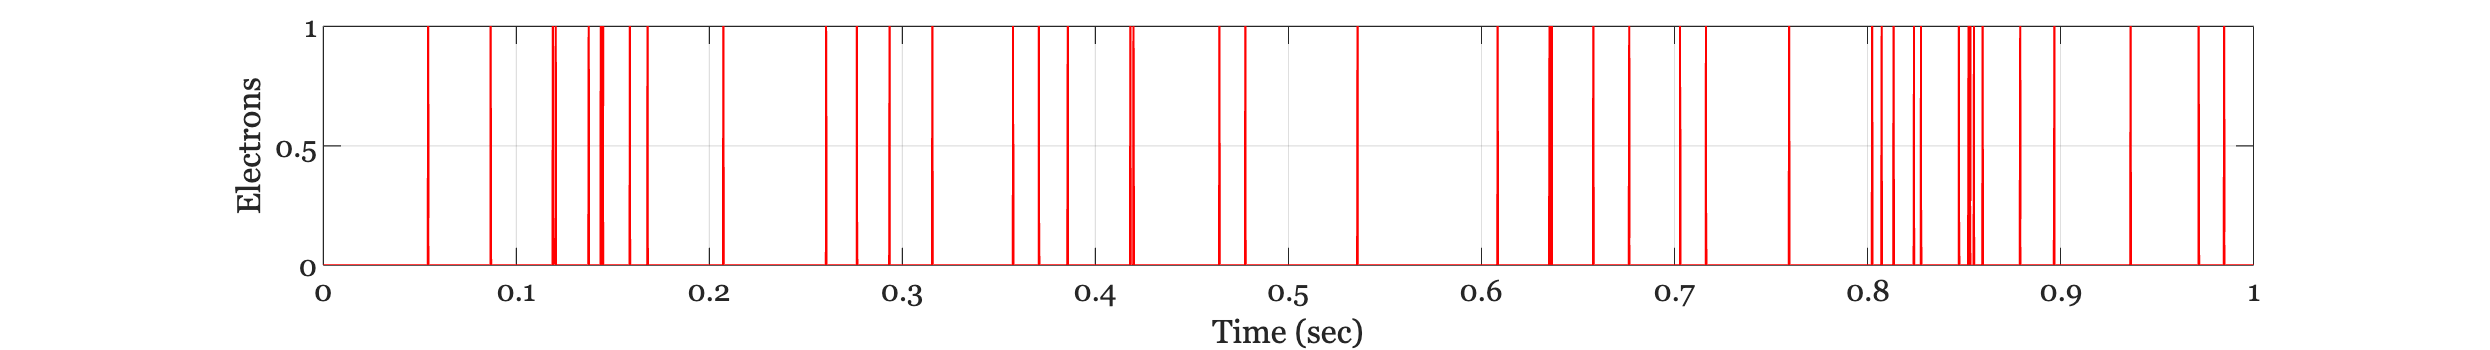

f = ieNewGraphWin; plot(T,electrons);
set(f,'Position',[100 100 256 64]);

xlabel('Time (sec)');
ylabel('Electrons'); grid on

fprintf('Combining photons with conversion likelihood, there were %d electrons\n',sum(electrons));

Combining photons with conversion likelihood, there were 46 electrons


## Equivalent calculation

Notice that we do not have to do the calculation in two steps.  We would have been the same distribution if we simply combined the two probabilities when we calculate the binomial distribution:

electrons2 = binornd(1,rho*epsilon,length(T),1);

This random sample is the equivalent of doing the calculation in two steps.

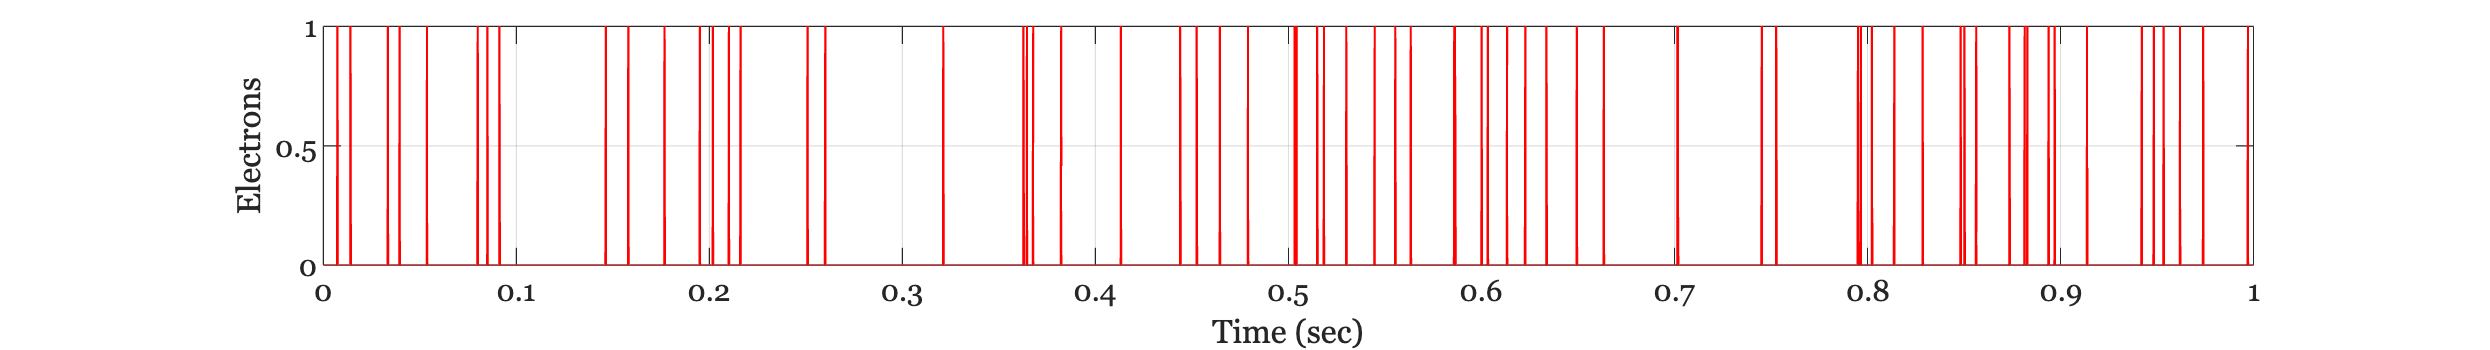

f = ieNewGraphWin; plot(T,electrons2);
set(f,'Position',[100 100 256 64]);
xlabel('Time (sec)');
ylabel('Electrons'); grid on


fprintf('The alternative calculation - use the binomial with the combined probabilities.\nThere were %d electrons\n',sum(electrons));

The alternative calculation - use the binomial with the combined probabilities.
There were 46 electrons


## What about detectors that are photon multipliers?

This  logic does not work well if there each photon can become multiple electrons, as we would see for photon multipliers, and avalanche photodiodes.  

I would like to see that calculation done correctly. 

Even so, in these applications people still use the Poisson as an approximation. But notice that when $\rho \epsilon > 1$ this calculation, based on the binomial, will not work.  Moreover, the property of the Poisson distribution (an equal chance of an event in every small interval of time) does not hold.  The generation of the electrons will be clustered around the times when a photon arrives. 

For a single photon avalanche detector (SPAD) the Poisson distribution may work well.  In that case, the Poisson distribution arises from the physics associated with the conversion of a single photon.